% Mann Raval (19BEC109) Maarjani Sanghavi (19BEC117)
% Digital Signal Processing
% Main program is used to extract notes from audio file
% Input file: FurElise_Slow.mp3
% relies on plotsound.m file for one (optional) function

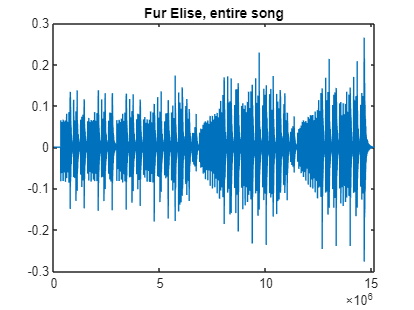


%% set up song
clear; 
clc; 
clf; 
close all;


mute = true; % set this to false to hear audio throughout program
             % useful for debugging

[song,Fs] = audioread('FurElise_Slow.mp3');
Fs = Fs*4;   % speed up song (original audio file is very slow)
figure, plot(song(:,1)), title('Fur Elise, entire song')


%% set parameters (change based on song)
% t1 and t2 are the start points and the points of the audio signal which
% is used for analysis
t1 = 2.9e6; t2 = 4.9e6;

% analyze a window of the song
y = song(t1:t2);
[~,n] = size(y);
t = linspace(t1,t2,n);
if ~mute, plotsound(y,Fs); end
audiowrite('fur_elise_window.wav',y,Fs);

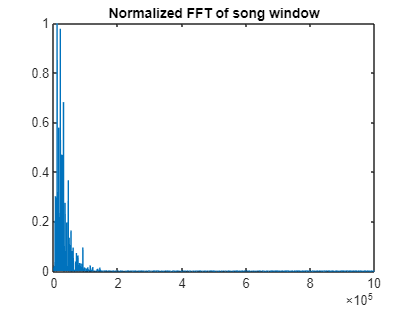


%% FFT of song
 Y = fft(y);
 Y_norm = abs(Y./max(Y));
 figure, plot(Y_norm), title('Normalized FFT of song window'), xlim([0 floor(n/2)])

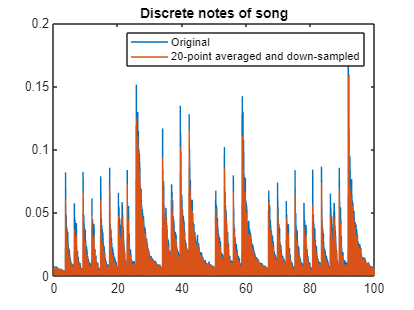

%% downsample by m
clc
m = 20;
Fsm = round(Fs/m);
p = floor(n/m);
y_avg = zeros(1,p);
for i = 1:p
    y_avg(i) = mean(y(m*(i-1)+1:m*i));
end
figure, plot(linspace(0,100,n),abs(y)), hold on
        plot(linspace(0,100,p),abs(y_avg))
        title('Discrete notes of song')
        legend('Original', '20-point averaged and down-sampled')

if ~mute, sound(y_avg,Fsm); end

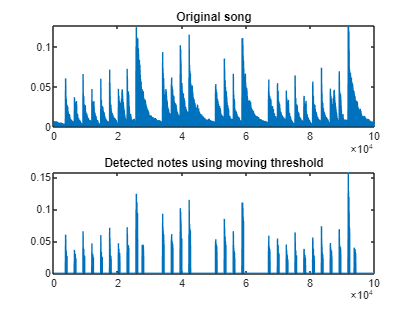

%% threshold to find notes
close all
y_thresh = zeros(1,p);
i = 1;
while (i <= p)
    thresh = 5*median(abs(y_avg(max(1,i-5000):i)));
    if (abs(y_avg(i)) > thresh)
        for j = 0:500
            if (i + j <= p)
                y_thresh(i) = y_avg(i);
                i = i + 1;
            end
        end
        i = i + 1400;
    end
    i = i + 1;
end

figure, subplot(2,1,1), plot(abs(y_avg)), title('Original song'), ylim([0 1.1*max(y_avg)])
        subplot(2,1,2), plot(abs(y_thresh)), title('Detected notes using moving threshold')

        
if ~mute, sound(y_thresh,round(Fsm)); end

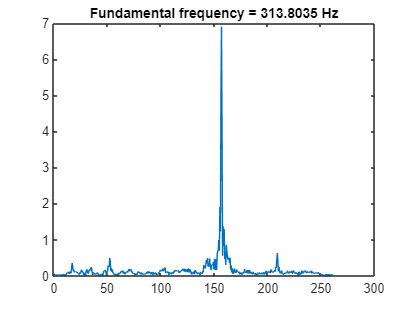

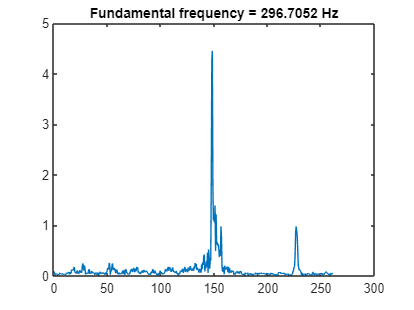

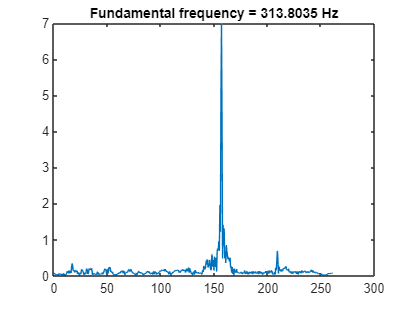

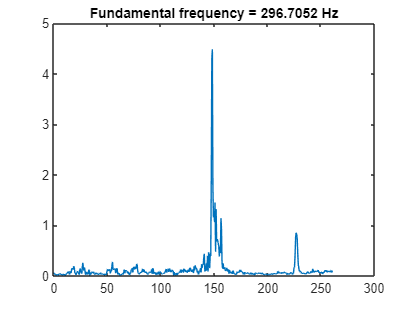

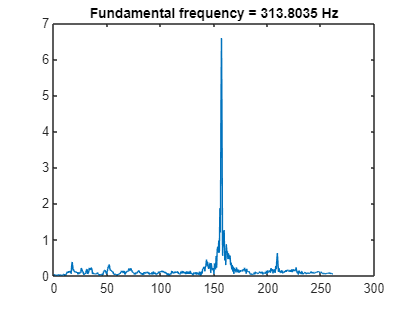

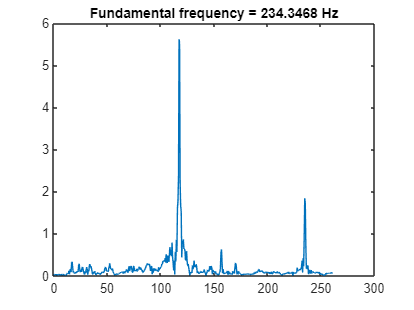

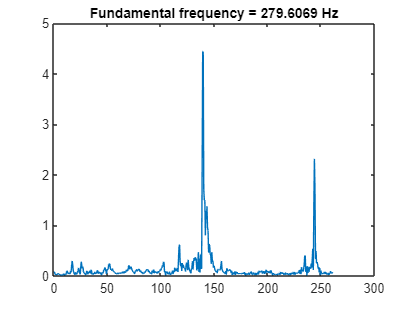

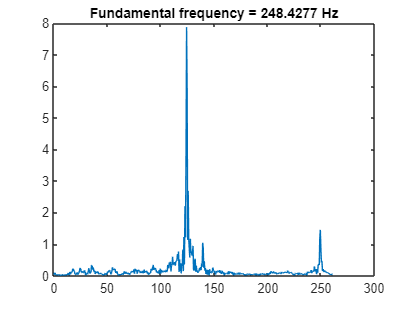

%% find frequencies of each note
clc; close all

i = 1;
i_note = 0;
while i < p
    j = 1;
    end_note = 0;
    while (((y_thresh(i) ~= 0) || (end_note > 0)) && (i < p))
        note(j) = y_thresh(i);
        i = i + 1;
        j = j + 1;
        if (y_thresh(i) ~= 0)
            end_note = 20;
        else
            end_note = end_note - 1;
        end
        if (end_note == 0)
           if (j > 25)
               note_padded = [note zeros(1,j)]; % pad note with zeros to double size (N --> 2*N-1)
               Note = fft(note_padded);
               Ns = length(note);
               f = linspace(0,(1+Ns/2),Ns);
               [~,index] = max(abs(Note(1:length(f))));
               if (f(index) > 20)
                   i_note = i_note + 1;
                   fundamentals(i_note) = f(index)*2;
                   figure, plot(f,abs(Note(1:length(f))))
                           title(['Fundamental frequency = ',num2str(fundamentals(i_note)),' Hz'])
                           %plot(note_padded)
               end
               i = i + 50;
           end
           clear note;
           break
        end
        
    end
    i = i + 1;
end


%% play back notes
amp = 1;
fs = 20500;  % sampling frequency
duration = .5;
recreate_song = zeros(1,duration*fs*length(fundamentals));
for i = 1:length(fundamentals)
    [letter(i,1),freq(i)]= FreqToNote(fundamentals(i));
    values = 0:1/fs:duration;
    a = amp*sin(2*pi*freq(i)*values*2);
    recreate_song((i-1)*fs*duration+1:i*fs*duration+1) = a;
    if ~mute, sound(a,fs); pause(.5); end
end
letter

letter = 29×1 string array
    "Eb4"
    "D4"
    "Eb4"
    "D4"
    "Eb4"
    "Bb3"
    "Db4"
    "B3"
    "Ab3"
    "Ab2"
    "B2"
    "Eb3"
    "Ab3"
    "Bb3"
    "Eb3"
    "G3"
    "Bb3"
    "B3"
    "Eb3"
    "Eb4"
    "D4"
    "Eb4"
    "D4"
    "Eb4"
    "Bb3"
    "Db4"
    "B3"
    "Ab3"
    "Ab2"


audiowrite('fur_elise_recreated.wav',recreate_song,fs);